## Setup

% Test Script for plotCR3BPOrbit Function

% Clear workspace and figures
clear; close all; clc;

cr3bp = CR3BPLibrary();  % Example object instantiation

%% Define CR3BP Parameters
%% Define Libration Points (Lpoints)
Lpoints = [
    0.8369,  0.0;                    % L1
    1.1557,  0.0;                    % L2
   -1.0051,  0.0;                    % L3
    0.5,     sqrt(3)/2;              % L4
    0.5,    -sqrt(3)/2;              % L5
];

Lpoints = [
    0.8369,  0.0;                    % L1
    1.1557,  0.0;                    % L2
    0,  0;                    % L3
    0,  0;              % L4
    0,  0;               % L5
];

mu = 0.012150585609624;   % Gravitational parameter for Earth-Moon system
n = 1;                    % Mean motion (normalized units)


%% Define Initial Condition (IC) for Gateway (Gw)
% IC_GW = [1.02134; 0; -0.18162; 0 ;-0.10176; 9.76561e-7];
% IC_GW = [0.8234, 0, 0.0172, 0, 0.1311, 0]';


% Tori initial conditions 
% IC_tori_N = [1.062432496 -6.23933E-27 0.200091981	1.09274E-14	-0.175700257 -1.15866E-13];
% IC_tori_N = [IC_tori_N 50];
% 
% IC_tori_S = [1.062432496 -6.23933E-27 -0.200091981	1.09274E-14	-0.175700257 -1.15866E-13];
% IC_tori_S = [IC_tori_S 49];
% IC_tori = [IC_tori_N ; IC_tori_S]
       
%% Define ODE Solver Options
optionsODE = odeset('RelTol',1e-13, 'AbsTol',1e-13);

% Find Gateway's period using the targeter function 
% [X0_optimized, Period_GW] = cr3bp.targeterPerpendicularXZ_FixedX(IC_GW, mu, n, 10, 1e-12, 1e-12, 100);
% IC_GW = [IC_GW; Period_GW];

% Propagate full Halo orbit
% [T_halo, Y_halo] = cr3bp.integrateCR3BP(X0_optimized, mu, n, [0 Period_GW], optionsODE);



### XAI Paper Orbits 

% NHL1s
    NHL1_1 = [0.8233798414, 0, 0.0172411539, 0, 0.1311291036, 0, 2.7450127781];
    NHL1_2 = [0.8801260326, 0, 0.1933262300, 0, 0.2235236647, 0, 2.1260109107];
    NHL1_3 = [0.9334801983, 0, 0.2497318810, 0, 0.0892287702, 0, 1.9359832911];    
    NHL1s = [NHL1_1 ; NHL1_2; NHL1_3];

% NHL2s
    NHL2_1 = [1.1418246386, 0, 0.16058698055, 0, -0.22272928884, 0, 3.1246625411];
    NHL2_2 = [1.1607918988, 0, 0.12271087295, 0, -0.20769013910, 0, 3.2746260398];
    NHL2_3 = [1.1808985498, 0, 0.00010295054075, 0, -0.15585631394, 0, 3.4155308066];    
    NHL2s = [NHL2_1; NHL2_2; NHL2_3];

% SHL2s;
    SHL2_1 = [0.9893775170083, 0, -0.1140502, 0, -0.01427275, 0, 0.7477784];
    SHL2_2 = [1.080636829806, 0, -0.2023607, 0, -0.1985649, 0, 2.348482];
    SHL2_3 = [1.180898549790, 0, -0.0001029505, 0, -0.1558563, 0, 3.415531];    
    SHL2s = [SHL2_1; SHL2_2; SHL2_3];

% SHL1s
    SHL1_1 = [0.823379841408243, 0, -0.0172411539186058, 0, 0.131129103578861, 0, 2.74501277811768];
    SHL1_2 = [0.870910917116380, 0, -0.189728451585385, 0, 0.238909240651915, 0, 2.24411433535841];
    SHL1_3 = [0.932636859229502, 0, -0.239386537601561, 0, 0.0954725059540738, 0, 1.88282038448969];    
    SHL1s = [SHL1_1;SHL1_2;SHL1_3];
        
    % Combine all IC families into one matrix
    allICs = [NHL1s; NHL2s; SHL2s; SHL1s];
    
    % Preallocate output (7th column = period)
    numOrbits       = size(allICs,1);
    ICs_with_period = zeros(numOrbits, 7);
    
    % Loop over each IC, compute optimized X0 and its period
    tol_target      = 1e-10;
    max_iter        = 100;
    guess_max_turns = 10;
    for i = 1:numOrbits
        x0_guess = allICs(i,1:6);
        % [X0_optimal, Period] → Period in nondimensional units
        [X0_optimal, Period_nd] = ...
          cr3bp.targeterPerpendicularXZ_FixedX(...
            x0_guess, mu, n, guess_max_turns, tol_target, tol_target, max_iter);
        ICs_with_period(i,:) = [X0_optimal(:).' Period_nd];
    end

Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 0.8234
  z0 = 0.0172
  vy0 = 0.1311
Period (Topt): 2.7450 (nd)
Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 0.8801
  z0 = 0.1933
  vy0 = 0.2235
Period (Topt): 2.1260 (nd)
Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 0.9335
  z0 = 0.2497
  vy0 = 0.0892
Period (Topt): 1.9360 (nd)
Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 1.1418
  z0 = 0.1606
  vy0 = -0.2227
Period (Topt): 3.1247 (nd)
Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 1.1608
  z0 = 0.1227
  vy0 = -0.2077
Period (Topt): 3.2746 (nd)
Convergence achieved after 1 iterations.
Optimized Initial Conditions:
  x0 = 1.1809
  z0 = 0.0001
  vy0 = -0.1559
Period (Topt): 3.4155 (nd)
Convergence achieved after 2 iterations.
Optimized Initial Conditions:
  x0 = 0.9894
  z0 = -0.1141
  vy0 = -0.0143
Period (Topt): 0.7478 (nd)
Converge

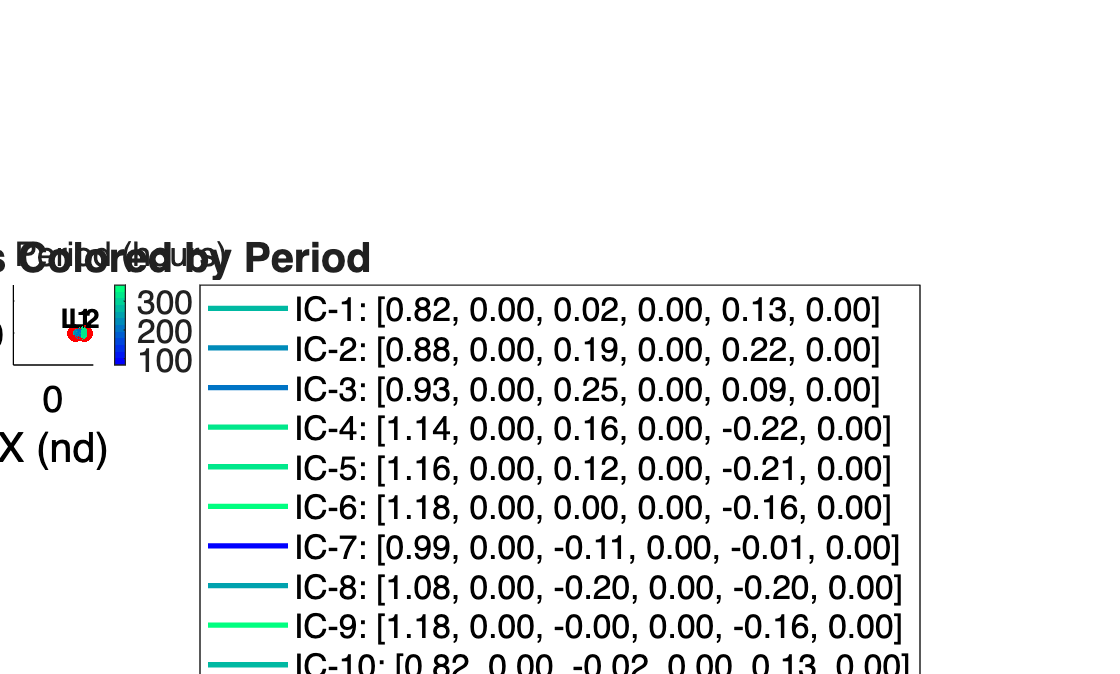

 
    
    % Now plot them, coloring by period
    Flag = 2;    % 1=JC, 2=period
    figure('Name','Orbits Colored by Period');
    cr3bp.plotCR3BPOrbit(...
        ICs_with_period, ...       % each row [x0 y0 z0 vx0 vy0 vz0 Period]
        Lpoints, mu, n, optionsODE, ...
        Flag, ...
        'blackBackground', false, ...
        'LineWidth', 2);
    title('CR3BP Orbits Colored by Period');

## Manifolds Test 1 

runCodeBelow = false;

if runCodeBelow 
    %% Manifold Computation
    % Compute monodromy matrix and eigenvectors
    Xaug0 = [X0_optimized; reshape(eye(6), 36, 1)]; % Initial state + STM
    [~, Y_aug] = ode45(@(t,X) cr3bp.augmentedDynamicsCR3BP(t,X,mu,n), [0 Period_GW], Xaug0, optionsODE);
    Phi_T = reshape(Y_aug(end, 7:end), 6, 6);       % Monodromy matrix
    
    % Eigenanalysis for manifold directions
    [eVecs, eVals] = eig(Phi_T);
    lambda = diag(eVals);
    [~, unstable_idx] = max(abs(lambda));  % Find unstable eigenvalue
    vu = real(eVecs(:, unstable_idx));     % Unstable eigenvector
    
    % Manifold generation parameters
    epsilon = 1e-6;       % Perturbation magnitude
    propTimeFactor = 1;
    prop_time = -Period_GW * propTimeFactor; % Backward propagation for unstable manifold
    
    % Generate manifold trajectories
    manifold_traj = [];
    sampleNumber = 350;
    perturbationScale = 10000;
    
    for i = 1:sampleNumber:length(Y_halo) % Sample every 50th point
        Xi = Y_halo(i, 1:6)';
        % Apply perturbation to both position and velocity
        X_pert = Xi + epsilon * vu./norm(vu(1:3)) * perturbationScale; % Scaled perturbation
        
        % Propagate perturbed state
        [~, Y_man] = cr3bp.integrateCR3BP(X_pert, mu, n, [0 prop_time], optionsODE);
        manifold_traj = [manifold_traj; Y_man]; %#ok<AGROW>
    end
    
    % Plot the orbit and manifold 
    Flag = 0;   
    figure('Name', 'Orbits Colored by Period');
    title('CR3BP Orbits Colored by Period');
    fig = cr3bp.plotCR3BPOrbit(Y_halo, Lpoints, mu, n, optionsODE, Flag, ...
        'blackBackground', true, ...
        'LineWidth', 3, ...
        'color', 'r', ...
        'states', true);
    
    cr3bp.plotCR3BPOrbit(manifold_traj, Lpoints, mu, n, optionsODE, Flag, ...
        'blackBackground', true, ...
        'LineWidth', 1, ...
        'color', 'g', ...
        'figureHandle', fig, ...
        'states', true);

end 

% eigenvector changes direction around each point in the orbit 
% take the initial premultiply by stm from that point to new point prop
% tiny branch of the periodic orbit
% propagation for full orbit from each 
% compute monodromy once, gives one unstable eigenvable


## Manifold Test 2 

runCodeBelow = false;

if runCodeBelow 
    
    % Parameters
    sampleInterval = 300;         % Sample every Nth point in the orbit
    perturbationScale = 1e-3;     % Optimal perturbation magnitude
    propagationFactor = 3;      % Propagation duration multiplier
    
    % Initialize IC storage with propagation times
    unstable_manifold_ICs = zeros(floor(length(Y_halo)/sampleInterval), 7);
    stable_manifold_ICs = zeros(floor(length(Y_halo)/sampleInterval), 7);
    
    % Main computation loop
    counter = 1;
    for i = 1:sampleInterval:length(Y_halo)
        try
            % Get current halo state
            Xi = Y_halo(i, 1:6)';
            
            % Compute local stability eigenvectors
            [vu, vs] = computeMonodromyEigenvectors(cr3bp, Xi, mu, n, Period_GW);
            
            % Store unstable manifold IC with propagation time
            unstable_manifold_ICs(counter,:) = [Xi + perturbationScale*vu/norm(vu); 
                                               -Period_GW*propagationFactor];
            
            % Store stable manifold IC with propagation time
            stable_manifold_ICs(counter,:) = [Xi + perturbationScale*vs/norm(vs);
                                             Period_GW*propagationFactor];
            
            counter = counter + 1;
            
        catch ME
            fprintf('Skipping point %d: %s\n', i, ME.message);
        end
    end
    
    %% ========================
    %  On-Demand Plotting
    %  ========================
    % Create base figure
    
    % Plot halo orbit
    fig = cr3bp.plotCR3BPOrbit([Y_halo], Lpoints, mu, n, optionsODE, 0, ...
        'blackBackground', true, ...
        'LineWidth', 2.5, ...
        'color', [1 0.2 0.2], ...    
        'states', true);
    
    % Plot unstable manifolds directly from ICs
    cr3bp.plotCR3BPOrbit(unstable_manifold_ICs, Lpoints, mu, n, optionsODE, 0, ...
        'blackBackground', true, ...
        'LineWidth', 1.2, ...
        'color', [0.2 0.8 1], ...
        'figureHandle', fig, ...
        'states', false, ...    % Critical flag for IC mode
        'LineStyle', '-.');
    
    % % Plot stable manifolds directly from ICs 
    % cr3bp.plotCR3BPOrbit(stable_manifold_ICs, Lpoints, mu, n, optionsODE, 0, ...
    %     'blackBackground', true, ...
    %     'LineWidth', 1.2, ...
    %     'color', [0.4 1 0.4], ...
    %     'figureHandle', fig, ...
    %     'states', false, ...    % Critical flag for IC mode
    %     'LineStyle', ':');
    % 
end 

## Plotting Test Cases 

runCodeBelow = true;

if runCodeBelow 

### Test Case 1: Plot Orbits Colored by Jacobi Constant (Flag = 1)

    % Flag = 1;  % Jacobi Constant Coloring
    % figure('Name', 'Orbits Colored by Jacobi Constant');
    % cr3bp.plotCR3BPOrbit(IC_GW, Lpoints, mu, n, optionsODE, Flag);

### Test Case 2: Plot Orbits Colored by Period (Flag = 2) and Black Background

    % Flag = 0;   
    % figure('Name', 'Orbits Colored by Period');
    % cr3bp.plotCR3BPOrbit(IC_GW, Lpoints, mu, n, optionsODE, Flag, 'blackBackground', true, 'LineWidth', 3, 'color', 'g');
    % title('CR3BP Orbits Colored by Period');

### Test Case 3: Plot Orbits with Custom Color and Line Properties

    % Flag = 0;  
    % figure('Name', 'Orbits with Custom Color and Line Properties')
    % cr3bp.plotCR3BPOrbit(IC_GW, Lpoints, mu, n, optionsODE, Flag, 'color', [0, 0.5, 0], 'LineWidth', 2, ...
    %     'LineStyle', '--', 'plotRealisticPrimaries', true, 'showLegends', false);               
    % title('CR3BP Orbits with Custom Color and Line Properties'); 

### Test Case 4: Plot Orbits with Initial Velocity Arrows

    % Flag = 0;  
    % figure('Name', 'Orbits with Initial Velocity Arrows');
    % cr3bp.plotCR3BPOrbit(IC_GW, Lpoints, mu, n, optionsODE, Flag, ...
    %     'arrows', true, ...                          % Enable velocity arrows
    %     'LineWidth', 1.5, ...                         
    %     'LineStyle', '-');                            
    % title('CR3BP Orbits with Initial Velocity Arrows');

### Test Case 5: Plot Orbits into an Existing Figure

    % % Create an existing figure handle
    % existingFig = figure('Name', 'Existing Figure for CR3BP Orbits');
    % 
    % % Plot orbits into the existing figure
    % cr3bp.plotCR3BPOrbit(IC_GW, Lpoints, mu, n, optionsODE, Flag, ...
    %     'figureHandle', existingFig, ...            
    %     'LineWidth', 1.5, ...                       
    %     'LineStyle', '-');                          
    % title(existingFig.CurrentAxes, 'CR3BP Orbits Plotted into Existing Figure');
end

## Test Functions Space

function [vu, vs] = computeMonodromyEigenvectors(lib, X0, mu, n, Period)
    % Compute monodromy matrix and eigenvectors for a given initial state
    Xaug0 = [X0; reshape(eye(6), 36, 1)]; % Initial state + STM
    
    % Integrate full period to get monodromy matrix
    [~, Y_aug] = ode45(@(t,X) lib.augmentedDynamicsCR3BP(t,X,mu,n),...
        [0 Period], Xaug0, odeset('RelTol',1e-12));
    
    Phi_T = reshape(Y_aug(end, 7:end), 6, 6); % Extract monodromy matrix
    
    % Eigenanalysis with sorting
    [eVecs, eVals] = eig(Phi_T);
    lambda = diag(eVals);
    
    % Sort by eigenvalue magnitude descending
    [~, idx] = sort(abs(lambda), 'descend');
    lambda = lambda(idx);
    eVecs = eVecs(:,idx);
    
    % Extract unstable (λ > 1) and stable (λ < 1) eigenvectors
    vu = real(eVecs(:,abs(lambda) > 1.1));
    vs = real(eVecs(:,abs(lambda) < 0.9));
end